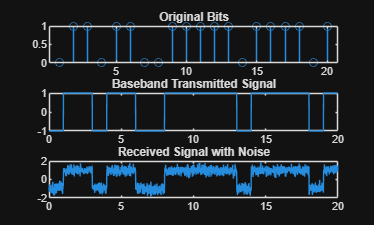

clc
clear
close all

%% Parameters
N = 1000;          % Number of bits
Tb = 1;            % Bit duration
fs = 100;          % Sampling frequency
t = 0:1/fs:Tb-1/fs;

%% Generate Random Bits
bits = randi([0 1],1,N);

%% NRZ Encoding
nrz = 2*bits - 1;

%% Pulse shaping (rectangular)
tx_signal = [];
for i = 1:N
    tx_signal = [tx_signal nrz(i)*ones(1,length(t))];
end

time = 0:1/fs:N*Tb-1/fs;

figure
subplot(3,1,1)
stem(bits(1:20))
title('Original Bits')

subplot(3,1,2)
plot(time(1:2000),tx_signal(1:2000))
title('Baseband Transmitted Signal')

%% Channel (AWGN)
snr = 10;
rx_signal = awgn(tx_signal,snr,'measured');

subplot(3,1,3)
plot(time(1:2000),rx_signal(1:2000))
title('Received Signal with Noise')


%% Receiver
samples = rx_signal(fs/2:fs:end);

%% Decision device
rx_bits = samples > 0;

%% BER Calculation
errors = sum(bits ~= rx_bits);
BER = errors/N;

fprintf('Bit Error Rate = %f\n',BER)

Bit Error Rate = 0.001000


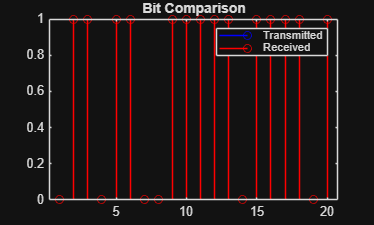


%% Plot comparison
figure
stem(bits(1:20),'b')
hold on
stem(rx_bits(1:20),'r')
legend('Transmitted','Received')
title('Bit Comparison')